load("modelo_lin.mat")

latmod

latmod =
 
  A = 
                 v           p           r         phi         psi
   v        -0.875      0.8751      -16.82       9.791           0
   p        -2.831      -16.14       3.377           0           0
   r         1.706      0.5154      -2.783           0           0
   phi           0           1     0.05385  -1.455e-24           0
   psi           0           0       1.001  -2.706e-23           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r   

Funciones de transferencia

TransferFunctions = tf(latmod)

TransferFunctions =
 
  From input "aileron" to output...
                 -19.49 s^2 - 214.7 s - 225.8
   beta:  -------------------------------------------
          s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
          -156.9 s^3 - 535 s^2 - 4302 s + 123.9
   p:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
         11.54 s^3 + 115.4 s^2 - 113.6 s - 2302
   r:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
                 -156.3 s^2 - 528.8 s - 4308
   phi:  -------------------------------------------
         s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
             11.55 s^3 + 115.6 s^2 - 113.7 s - 2305
   psi:  -----------------------------------------------
         s^5 + 19.8 s^4 + 90.9 s^3 + 505.1 s^2 + 6.979 s
 
  From input "rudder" to output...
            0.3128 s^3 + 87.06 s^2 + 1309 s - 209.3
   beta:  -------------------------------------------
          s^4 + 19.8

Función


$$\frac{p}{\textrm{aileron}}$$


G1 = TransferFunctions(2,1)

G1 =
 
  From input "aileron" to output "p":
     -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



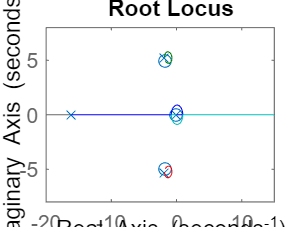

rlocus(G1)

kd1 = 0.106;
Go1 = feedback(kd1*G1,1)

Go1 =
 
  From input "aileron" to output:
     -16.63 s^3 - 56.71 s^2 - 456 s + 13.14
  ---------------------------------------------
  s^4 + 3.164 s^3 + 34.19 s^2 + 49.08 s + 20.12
 
Continuous-time transfer function.



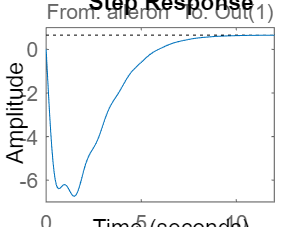

step(Go1)

stepinfo(Go1)

ans = struct with fields:
         RiseTime: 2.7315
    TransientTime: 7.8207
     SettlingTime: 10.5372
      SettlingMin: 0.5886
      SettlingMax: 0.6499
        Overshoot: 0
       Undershoot: 1.0317e+03
             Peak: 6.7379
         PeakTime: 1.4884


Función


$$\frac{r}{\textrm{rudder}}$$


G2 = TransferFunctions(3,2)

G2 =
 
  From input "rudder" to output "r":
     -82.27 s^3 - 1393 s^2 - 1237 s - 2365
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



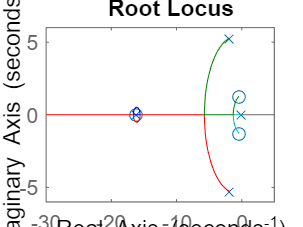

rlocus(-G2)

kd2 = -0.2;
Go2 = feedback(kd2*G2,1)

Go2 =
 
  From input "rudder" to output:
     16.45 s^3 + 278.6 s^2 + 247.3 s + 472.9
  ---------------------------------------------
  s^4 + 36.25 s^3 + 369.6 s^2 + 752.4 s + 479.9
 
Continuous-time transfer function.



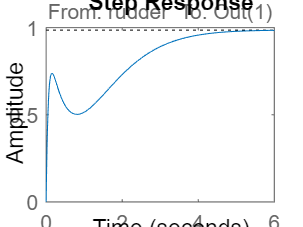

step(Go2)

stepinfo(Go2)

ans = struct with fields:
         RiseTime: 2.9611
    TransientTime: 4.2761
     SettlingTime: 4.2761
      SettlingMin: 0.8874
      SettlingMax: 0.9854
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9854
         PeakTime: 6.9373


Retroalimentación

kd = [kd1 0;0 kd2]

kd =     0.1060         0
         0   -0.2000


feedin = [1 2]

feedin =      1     2


feedout = [2 3]

feedout =      2     3


CASLatMod = feedback(latmod,kd,feedin,feedout)

CASLatMod =
 
  A = 
                 v           p           r         phi         psi
   v        -0.875      0.8751      -15.76       9.791           0
   p        -2.831      0.4939       2.372           0           0
   r         1.706     -0.7074      -19.24           0           0
   phi           0           1     0.05385  -1.455e-24           0
   psi           0           0       1.001  -2.706e-23           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r

Funciones de transferencia

CASTransferFunctions = tf(CASLatMod)

CASTransferFunctions =
 
  From input "aileron" to output...
                  -18.77 s^2 - 341.6 s - 1720
   beta:  -------------------------------------------
          s^4 + 19.62 s^3 + 37.94 s^2 + 82.38 s + 493
 
         -156.9 s^3 - 3128 s^2 - 6321 s + 123.9
   p:  -------------------------------------------
       s^4 + 19.62 s^3 + 37.94 s^2 + 82.38 s + 493
 
         11.54 s^3 + 115.4 s^2 - 113.6 s - 2302
   r:  -------------------------------------------
       s^4 + 19.62 s^3 + 37.94 s^2 + 82.38 s + 493
 
                 -156.3 s^2 - 3122 s - 6327
   phi:  -------------------------------------------
         s^4 + 19.62 s^3 + 37.94 s^2 + 82.38 s + 493
 
             11.55 s^3 + 115.6 s^2 - 113.7 s - 2305
   psi:  -----------------------------------------------
         s^5 + 19.62 s^4 + 37.94 s^3 + 82.38 s^2 + 493 s
 
  From input "rudder" to output...
           0.3128 s^3 + 81.86 s^2 - 63.87 s - 166.7
   beta:  -------------------------------------------
          s^4 + 19

Función


$$\frac{p}{\textrm{aileron}}$$


G11 = CASTransferFunctions(2,1)

G11 =
 
  From input "aileron" to output "p":
    -156.9 s^3 - 3128 s^2 - 6321 s + 123.9
  -------------------------------------------
  s^4 + 19.62 s^3 + 37.94 s^2 + 82.38 s + 493
 
Continuous-time transfer function.



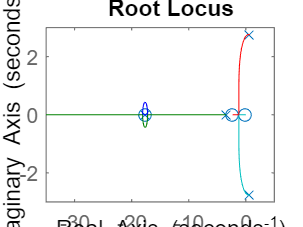

rlocus(-G11)

kp1 = -0.12;
Go11 = feedback(kp1*G11,1)

Go11 =
 
  From input "aileron" to output:
     18.83 s^3 + 375.4 s^2 + 758.5 s - 14.87
  ---------------------------------------------
  s^4 + 38.45 s^3 + 413.3 s^2 + 840.9 s + 478.2
 
Continuous-time transfer function.



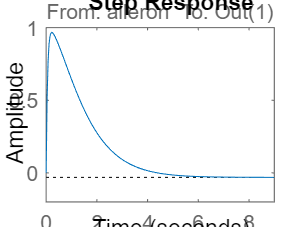

step(Go11)

stepinfo(Go11)

ans = struct with fields:
         RiseTime: 2.0811
    TransientTime: 4.8174
     SettlingTime: 8.0466
      SettlingMin: -0.0311
      SettlingMax: -0.0281
        Overshoot: 0
       Undershoot: 3.1079e+03
             Peak: 0.9667
         PeakTime: 0.2314


Función


$$\frac{r}{\textrm{rudder}}$$


G22 = CASTransferFunctions(3,2)

G22 =
 
  From input "rudder" to output "r":
    -82.27 s^3 - 18.73 s^2 - 166.5 s - 2365
  -------------------------------------------
  s^4 + 19.62 s^3 + 37.94 s^2 + 82.38 s + 493
 
Continuous-time transfer function.



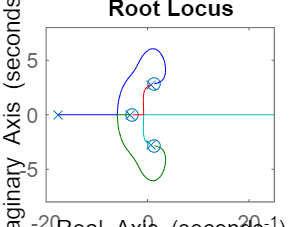

rlocus(G22)

kp2 = 0.15;
Go22 = feedback(kp2*G22,1)

Go22 =
 
  From input "rudder" to output:
    -12.34 s^3 - 2.809 s^2 - 24.98 s - 354.7
  --------------------------------------------
  s^4 + 7.277 s^3 + 35.13 s^2 + 57.4 s + 138.3
 
Continuous-time transfer function.



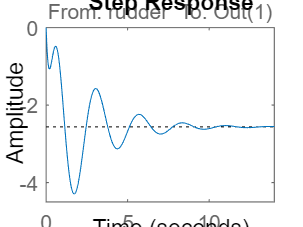

step(Go22)

ans = struct with fields:
         RiseTime: 1.0727
    TransientTime: 9.9146
     SettlingTime: 9.9146
      SettlingMin: -4.2954
      SettlingMax: -1.5729
        Overshoot: 67.5402
       Undershoot: 0
             Peak: 4.2954
         PeakTime: 1.7180


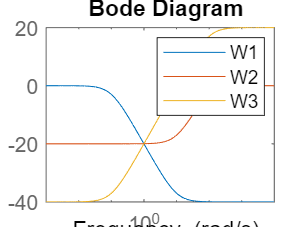

stepinfo(Go22)